clc; clear; close all

syms x(t) theta(t) F
syms M m g l b I
assume([g l m M b] > 0)


P = (M+m)*I + M*m*l^2

$$P = M\,m\,l^{2}+\text{I}\,\left(M+m\right)$$

eqn1 = (M+m)*diff(x,t) - m*l*cos(theta)*diff(theta,2) + m*l*sin(theta)*(diff(theta))^2 == F-diff(x)*b

$$eqn1(t) = -l\,m\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+l\,m\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+\left(M+m\right)\,\frac{\partial }{\partial t}x\left(t\right)=F-b\,\frac{\partial }{\partial t}x\left(t\right)$$

eqn2 = m*diff(x,2)*l*cos(theta) - m*l^2 * diff(theta,2) + m*g*l*sin(theta) == I * diff(theta,2)

$$eqn2(t) = -m\,l^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+m\,\cos\left(\theta \left(t\right)\right)\,l\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+g\,m\,\sin\left(\theta \left(t\right)\right)\,l=\text{I}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)$$

% solve([eqn1 eqn2],[x(t) theta(t)])


#### In vergelijking met MathWorks help center:

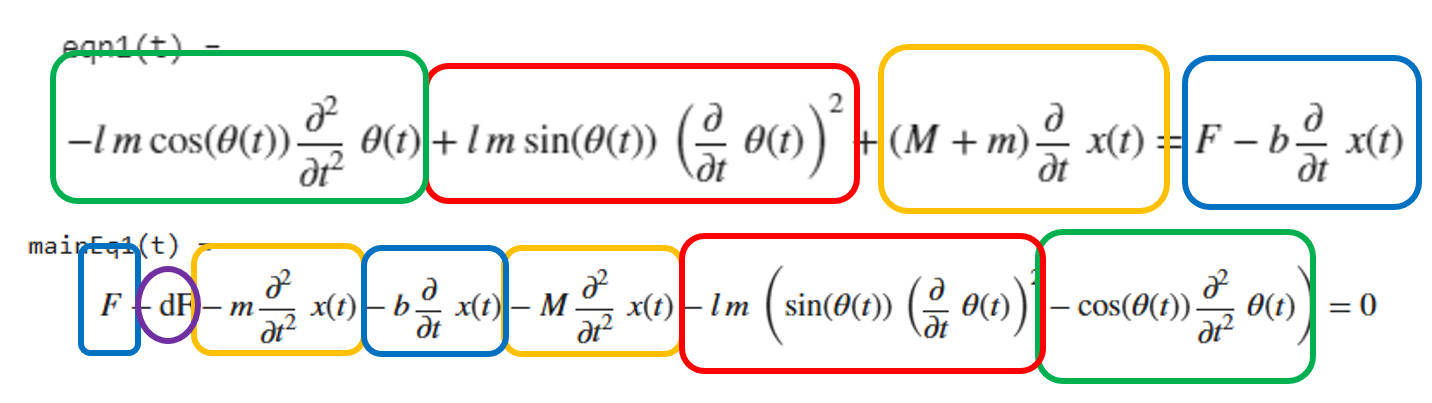

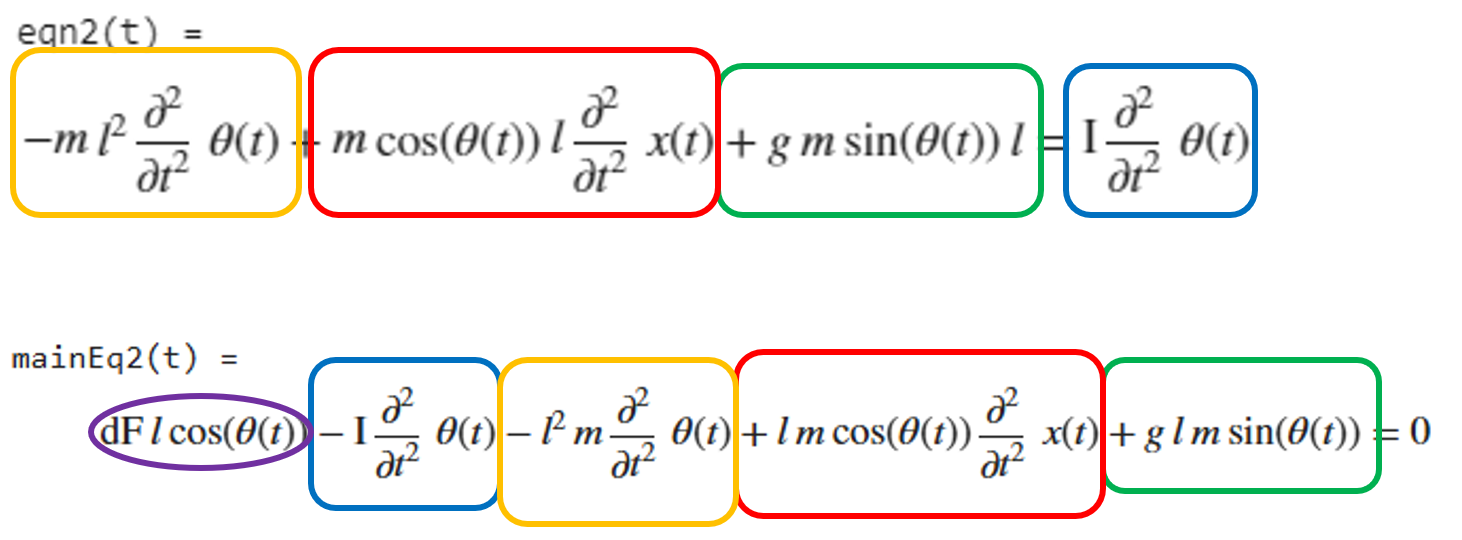

In de afbeeldingen zijn de bovenste regels onze vgl'en, onderste die van MathWorks. Komen exact overeen op een dF term na. TBD wa da juist wilt zeggen. Gemini zegt:

"**Wat betreft de $dF$ term bij MathWorks: **Dat is de afgeleide van de kracht. In de meeste mechanische systemen is de kracht een directe input ($u$), geen toestand waarvan de afgeleide ertoe doet. Omdat jouw vergelijking $F$ aan de rechterkant heeft staan als een "stap" of "impuls", kun je die $dF$ negeren voor je State-Space model."

[ssEqs,states] = odeToVectorField([eqn1 eqn2]);
simplify(ssEqs)

$$ans = \left(\begin{array}{c} Y_{2}\\ \frac{l\,m\,\sin\left(Y_{1}\right)\,{Y_{2}}^{2}-F+M\,Y_{4}+b\,Y_{4}+m\,Y_{4}}{l\,m\,\cos\left(Y_{1}\right)}\\ Y_{4}\\ \frac{\text{I}\,M\,Y_{4}-F\,\text{I}+l^{2}\,m^{2}\,Y_{4}+\text{I}\,b\,Y_{4}+\text{I}\,m\,Y_{4}-F\,l^{2}\,m+l^{3}\,m^{2}\,\sin\left(Y_{1}\right)\,{Y_{2}}^{2}+M\,l^{2}\,m\,Y_{4}+b\,l^{2}\,m\,Y_{4}-\frac{g\,l^{2}\,m^{2}\,\sin\left(2\,Y_{1}\right)}{2}+\text{I}\,l\,m\,\sin\left(Y_{1}\right)\,{Y_{2}}^{2}}{l^{2}\,m^{2}\,{\cos\left(Y_{1}\right)}^{2}} \end{array}\right)$$

A = [0 1 0 0; 0 (-b*(I+m*l^2))/P (m^2*l^2*g)/P 0; 0 0 0 1; 0 (-b*m*l)/P, m*g*l*(m+M)/P 0]

$$A = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & -\frac{b\,\left(m\,l^{2}+\text{I}\right)}{\sigma_{1}} & \frac{g\,l^{2}\,m^{2}}{\sigma_{1}} & 0\\ 0 & 0 & 0 & 1\\ 0 & -\frac{b\,l\,m}{\sigma_{1}} & \frac{g\,l\,m\,\left(M+m\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=M\,m\,l^{2}+\text{I}\,\left(M+m\right) \end{array}$$

B = [0 (I + m*l^2)/P 0 (m*l)/P]

$$B = \left(\begin{array}{cccc} 0 & \frac{m\,l^{2}+\text{I}}{M\,m\,l^{2}+\text{I}\,\left(M+m\right)} & 0 & \frac{l\,m}{M\,m\,l^{2}+\text{I}\,\left(M+m\right)} \end{array}\right)$$

C = [1 0 0 0; 0 0 1 0];
D = 0;


Mn = 0.5;
mn = 0.2;
gn = 9.81;
ln = 0.15;
bn = 0.1;
In = 1/12 * mn * (2*ln)^2

In = 0.0015


Pn = (Mn+mn)*In + Mn*mn*ln^2

Pn = 0.0033


%(mn*ln)/(Mn*mn*ln^2 + In*(Mn + mn))

An = eval(subs(A,[M m g l b I],[Mn mn gn ln bn In]));

Bn = eval(subs(B,[M m g l b I],[Mn mn gn ln bn In]))';

Cn = eval(subs(C,[M m g l b I],[Mn mn gn ln bn In]));

Dn = eval(subs(D,[M m g l b I],[Mn mn gn ln bn In]));




sys = ss(An,Bn,Cn,Dn,'InputName',{'F'},'OutputName',{'x','\theta'})


sys =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2        0  -0.1818    2.675        0
   x3        0        0        0        1
   x4        0  -0.9091    62.43        0
 
  B = 
           F
   x1      0
   x2  1.818
   x3      0
   x4  9.091
 
  C = 
           x1  x2  x3  x4
   x        1   0   0   0
   \theta   0   0   1   0
 
  D = 
           F
   x       0
   \theta  0
 
Continuous-time state-space model.


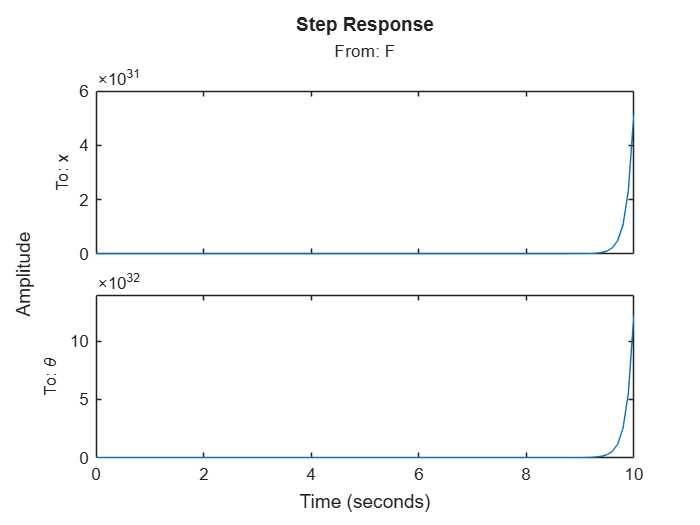

step(sys,10)

H = tf(sys)


H =
 
  From input "F" to output...
           1.818 s^2 - 3.23e-15 s - 89.18
   x:  --------------------------------------
       s^4 + 0.1818 s^3 - 62.43 s^2 - 8.918 s
 
                   9.091 s - 9.511e-17
   \theta:  ----------------------------------
            s^3 + 0.1818 s^2 - 62.43 s - 8.918
 
Continuous-time transfer function.


% Kloppen de coefficiënten in transferfunctie: 
(mn*ln)/(In*(Mn+mn) + Mn*mn*ln^2) %9.091?

ans = 9.0909

(In + mn*ln^2)*bn/(In*(Mn+mn) + Mn*mn*ln^2) %0.1818?

ans = 0.1818

-(Mn+mn)*(mn*gn*ln)/(In*(Mn+mn) + Mn*mn*ln^2) %62.43?

ans = -62.4273

-(mn*gn*ln*bn)/(In*(Mn+mn) + Mn*mn*ln^2) %8.918?

ans = -8.9182

eig(An)

ans =          0
   -0.1428
   -7.9210
    7.8820


syms s
H_s = Cn * (s*eye(size(An,1)) - An)^(-1) * Bn

$$H\_s = \begin{array}{l} \left(\begin{array}{c} -\frac{20\,\left(110\,s^{2}-6867\right)}{\sigma_{1}}-\frac{29430}{\sigma_{1}}\\ \frac{2000}{\sigma_{2}}-\frac{1000\,\left(11\,s+2\right)}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=11\,\left(-110\,s^{4}-20\,s^{3}+6867\,s^{2}+981\,s\right)\\ \sigma_{2}=11\,\left(-110\,s^{3}-20\,s^{2}+6867\,s+981\right) \end{array}$$

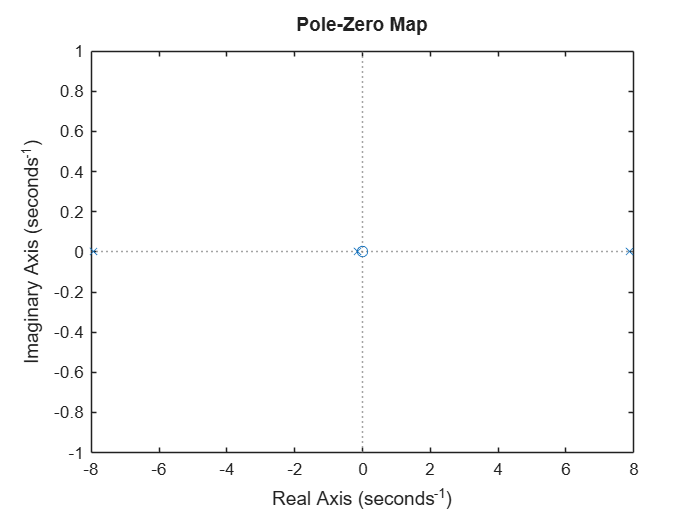

figure;
pzmap(H(2,1))

pole(H(1,1))

ans =          0
    7.8820
   -7.9210
   -0.1428


pole(H(2,1))

ans =     7.8820
   -7.9210
   -0.1428


T_sample = 0.05;
sysd = c2d(sys, T_sample); Hd = tf(sysd)


Hd =
 
  From input "F" to output...
       0.002272 z^3 - 0.002561 z^2 - 0.002539 z + 0.002265
   x:  ---------------------------------------------------
          z^4 - 4.149 z^3 + 6.288 z^2 - 4.13 z + 0.991
 
            0.01148 z^2 - 3.497e-05 z - 0.01144
   \theta:  -----------------------------------
             z^3 - 3.149 z^2 + 3.139 z - 0.991
 
Sample time: 0.05 seconds
Discrete-time transfer function.


rank(ctrb(sysd))

ans = 4

rank(obsv(sysd)) 

ans = 4

p2 = pole(sysd(2))

p2 =     1.4830
    0.9929
    0.6730
    1.0000


z2 = zero(sysd(2))

z2 =    -0.9970
    1.0000
    1.0000


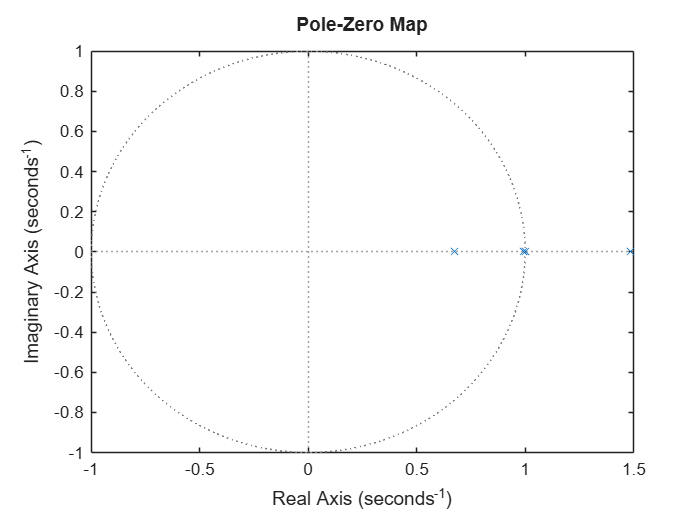

figure;
pzmap(sysd)

% 1. Data inladen
states_data = readmatrix('pendulum_states.csv')

states_data =          0         0    0.0100         0
    0.0023    0.0924    0.0223    0.4962
    0.0093    0.1871    0.0608    1.0655
    0.0211    0.2874    0.1314    1.7927
    0.0382    0.3955    0.2443    2.7714
    0.0608    0.5088    0.4142    4.0868
    0.0889    0.6111    0.6591    5.7646
    0.1210    0.6629    0.9955    7.7319
    0.1534    0.6067    1.4359    9.9290
    0.1791    0.3970    1.4960         0
    0.2007    0.4653    1.4960         0
    0.2256    0.5332    1.4960         0
    0.2540    0.6006    1.4960         0
    0.2857    0.6675    1.4960         0
    0.3207    0.7339    1.4960         0


inputs_data = readmatrix('pendulum_inputs.csv')

inputs_data =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


% Tijdstappen definiëren (T = 0.05s in je Python code)
T = 0.05;
t_sim = 0:T:(length(states_data)-1)*T;

% 2. Extractie van de gesimuleerde variabelen (Python)
x_sim = states_data(:, 1);     % Cart position
theta_sim = states_data(:, 3); % Pendulum angle

% % 3. Theoretische respons berekenen (MATLAB model)
% % We simuleren de respons op een stap van 1 Newton
% opt = stepDataOptions('StepAmplitude', 1);
% [y_theory, t_theory] = step(sysd, t_sim(end), opt)

u_sim = ones(size(t_sim)) * 1; 
x0 = [0; 0; 0.01; 0]; 

% 4. Simuleer met lsim
[y_theory, t_theory] = lsim(sysd, u_sim, t_sim, x0)

y_theory = 1.0e+67 *

         0    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000


t_theory =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500
    0.5000
    0.5500
    0.6000
    0.6500
    0.7000


x_theory = y_theory(:, 1);
theta_theory = y_theory(:, 2);


% De limieten definiëren
rail_max = 0.9;
rail_min = -0.95;
phi_max = pi/2.1;

% De theoretische data filteren (clamping)
theta_theory_clamped = theta_theory;
theta_theory_clamped(theta_theory > phi_max) = phi_max;
theta_theory_clamped(theta_theory < -phi_max) = -phi_max;

x_theory_clamped = x_theory;
x_theory_clamped(x_theory > rail_max) = rail_max;
x_theory_clamped(x_theory < rail_min) = rail_min;

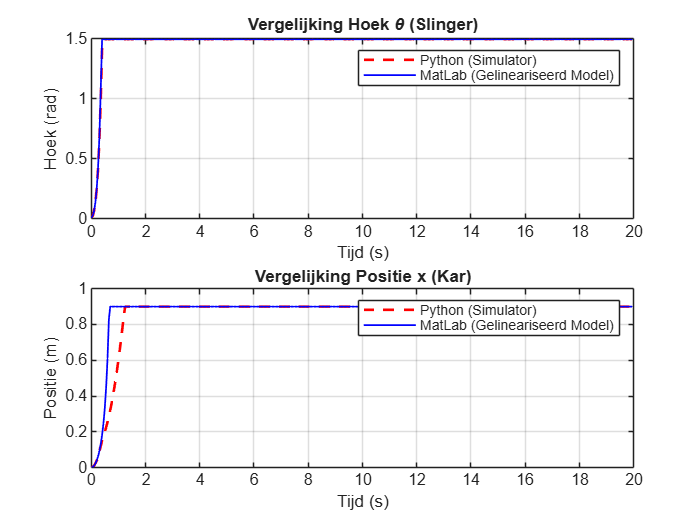

% 4. Visualisatie / Vergelijking
figure;

subplot(2,1,1);
plot(t_sim, theta_sim, 'r--', 'LineWidth', 1.5); hold on;
plot(t_theory, theta_theory_clamped, 'b', 'LineWidth', 1);
title('Vergelijking Hoek \theta (Slinger)');
xlabel('Tijd (s)'); ylabel('Hoek (rad)');
legend('Python (Simulator)', 'MatLab (Gelineariseerd Model)');
grid on;

subplot(2,1,2);
plot(t_sim, x_sim, 'r--', 'LineWidth', 1.5); hold on;
plot(t_theory, x_theory_clamped, 'b', 'LineWidth', 1);
title('Vergelijking Positie x (Kar)');
xlabel('Tijd (s)'); ylabel('Positie (m)');
legend('Python (Simulator)', 'MatLab (Gelineariseerd Model)');
grid on;

% Slechte x doordat theta niet meer klein blijft. Sin(theta) /= theta ->
% Model "denkt" dus dat de zwaartekracht veel harder aan de slinger trekt dan in de werkelijkheid het geval is